# Exercise-1 Perform Visiblity Analysis for an NTN Satellite and a UE

In this Exercise, You will: 

- Set up a visibility access analysis between a satellite and a UE.

- Calculates the time intervals over the course of a day when the satellite is in view of the UE.

- Computes the Propogation Delay and Doppler shift as the satellite moves in its orbit.

## Create Satellite Scenario

all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows
startTime = datetime(2020,8,19,20,55,0); % 19 August 2020 8:55 PM UTC
stopTime = startTime + days(0.5);          % 20 August 2020 8:55 PM UTC
sampleTime = 60;                         % seconds
sc = satelliteScenario(startTime,stopTime,sampleTime);

## Launch Satellite Scenario Viewer

Use `satelliteScenarioViewer` to launch a Satellite Scenario Viewer.

vwr = satelliteScenarioViewer(sc,Dimension="3D");

# Task #1/8 Add a Satellite to the Scenario

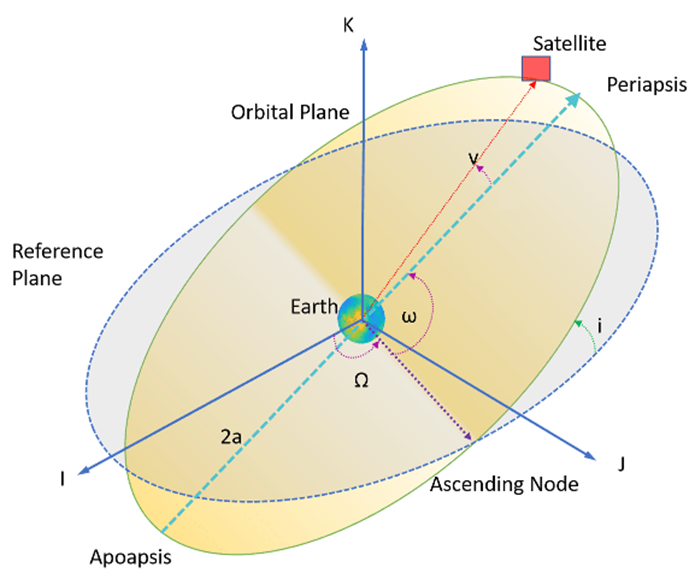

**Orbital Elements**

semiMajorAxis = 7371e3;               % meters
eccentricity = 0;
inclination = 45;                   % degrees
rightAscensionOfAscendingNode = 0; % degrees
argumentOfPeriapsis = 0;           % degrees
trueAnomaly = 0;                   % degrees
orbProp = "two-body-keplerian";
satName = "Satellite";
% Hint: doc satellite (see "Syntax" section)
% Use satellite() function to Add the satellite.
% Store satellite in a variable named "sat"
% Note : use the following values to start with
%  sc
%  semiMajorAxis
%  eccentricity
%  inclination
%  rightAscensionOfAscendingNode
%  argumentOfPeriapsis
%  trueAnomaly
%  OrbitPropagator=orbProp
%  Name=satName

% Enter Code Here
sat = satellite(sc, ...
  semiMajorAxis, ...
  eccentricity, ...
  inclination, ...
  rightAscensionOfAscendingNode, ...
  argumentOfPeriapsis, ...
  trueAnomaly, ...
  OrbitPropagator=orbProp, ...
  Name=satName);

# Task #2/8 Add Conical Sensor to Satellite

maxViewingAngle = 60;
csName = "sensor";
% Add the conical sensor.  Hint:  doc conicalSensor (see "Syntax" section)
% Use conicalSensor()  to Add the conical sensor.
% Store conical sensor in a variable named "sensor"
% Note : use the following values to start with
%   sat
%   MaxViewAngle=maxViewingAngle
%   Name=csName

% Enter Code Here 
sensor = conicalSensor(sat, ...
  MaxViewAngle=maxViewingAngle, ...
  Name=csName);

# Task #3/8 Enable Field of View Visualization

% Hint:  Hint:  doc fieldOfView (see "Syntax" section)
% Use fieldOfView() function to Enable field of view visualization
% Note : use the following values to start with
% sensor

% Enter Code Here 
fieldOfView(sensor);

# Task #4/8  Add a UE to Scenario

%Bangalore's latitude and longitude are approximately 12°58′N and 77°35′E. 
latitude = 12.58;  % degrees
longitude = 77.35; % degrees
altitude = 100; % meters
ueName = "UE-1";
% Hint:  Hint:  doc groundStation (see "Syntax" section)
% Use groundStation() function to Add the UE.
% Store ground station in a variable named "ue"
% Note : use the following values to start with
%  sc
%  latitude
%  longitude
%  Name=ueName
%  Altitude=altitude

% Enter Code Here 
ue = groundStation(sc,...
  latitude, ...
  longitude,...
  Name=ueName, ...
  Altitude=altitude);

# Task #5/8 Point Satellite at Desired Asset

For maximum visibility from the satellite to the desired asset, the satellite must point at the UE.

asset = "nadir";
% Point the satellite at the desired asset. 
% Use pointAt() function
% Hint:  Hint:  doc pointAt (see "Syntax" section)
% Note : use the following values to start with
% sat
% asset

% Enter code here
pointAt(sat,asset);

# Task #6/8 Add Access Analysis and Visualize Scenario

Use `access` to set up a visbility access analysis from the satellite camera to the UE.

% Add access analysis.  Hint:  doc access (see "Syntax" section)
% % Use access() to add access analysis
% Note : use the following values to start with
% sensor
% ue

% Enter code here
ac = access(sensor,ue);

# Task #7/8 Determine Times When Access Is Achieved

Use  `accessIntervals` to determine the times when visibility access is achieved.  The a`ccessIntervals` method outputs a table of the start and stop times of access that represent the intervals during which the satellite can see the UE.

% Calculate access intervals.  Hint:  doc accessIntervals (see "Syntax"
% % Use accessIntervals() function
% Note : use the following values to start with
% ac

% Enter code here
accessIntervals(ac)

ans = 6×8 table
     Source     Target    IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    ______    ______________    ____________________    ____________________    ________    __________    ________

    "sensor"    "UE-1"          1           19-Aug-2020 20:55:00    19-Aug-2020 21:06:00       660          1            1    
    "sensor"    "UE-1"          2           19-Aug-2020 22:40:00    19-Aug-2020 22:57:00      1020          2            2    
    "sensor"    "UE-1"          3           20-Aug-2020 00:35:00    20-Aug-2020 00:45:00       600          3            3    
    "sensor"    "UE-1"          4           20-Aug-2020 04:26:00    20-Aug-2

#### Calculate the Doppler shift at the UE

% Calculate orbital period
mu = 3.986004418e14;             % Earth's gravitational parameter (m^3/s^2)
T = 2*pi*sqrt(semiMajorAxis^3 / mu)/60;  % period in minutes
period = 1:ceil(T);
calculateDoppler = true;
if calculateDoppler
    freq = 5e9;  % Hz
    [frequencyShift,timeOut,dopplerInfo] = dopplershift(sat,ue,Frequency=freq);
    frequencyRate = dopplerInfo.DopplerRate;
    relativeVelocity = dopplerInfo.RelativeVelocity;
    subplot(2,2,1);
    plot(timeOut(period),frequencyShift(period)/1e3)       % Doppler shift in kilohertz (kHz)
    title("Doppler Shift vs. Time")
    xlabel("Simulation Time")
    ylabel("Doppler Shift (kHz)")
    grid on
    subplot(2,2,2);
    plot(timeOut,frequencyShift/1e3)       % Doppler shift in kilohertz (kHz)
    title("Doppler Shift vs. Time")
    xlabel("Simulation Time")
    ylabel("Doppler Shift (kHz)")
    grid on
end

#### Calculate the propagation delay at the UE

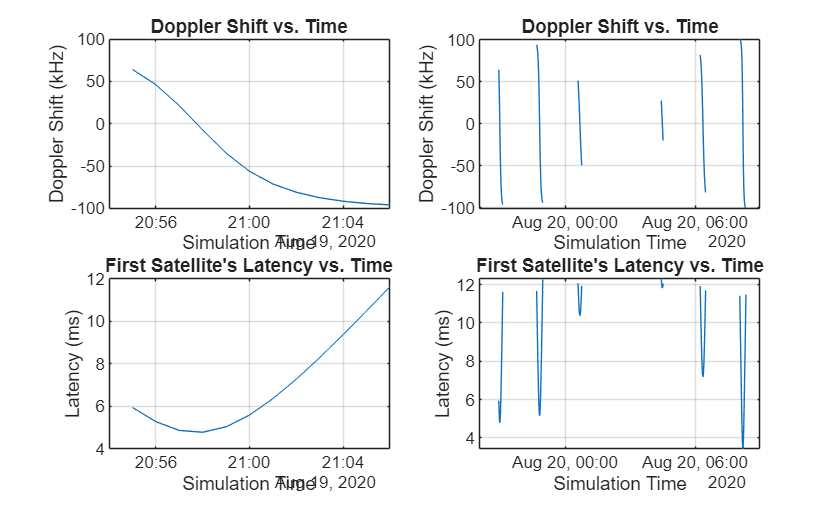

calculateLatency = true;
if calculateLatency
    [delay,time] = latency(sat,ue);
    subplot(2,2,3);
    plot(time(period),delay(period)*1000)                  % Plot in milliseconds
    title("First Satellite's Latency vs. Time")
    xlabel("Simulation Time")
    ylabel("Latency (ms)")
    grid on
    subplot(2,2,4);
    plot(time,delay*1000)                  % Plot in milliseconds
    title("First Satellite's Latency vs. Time")
    xlabel("Simulation Time")
    ylabel("Latency (ms)")
    grid on
end

# Task #8/8 Play the Scenario

Use `play` to visualize the scenario simulation from its start time to stop time.  Set the playback speed to be 1000 times real time.  A line from the satellite to the UE appears when visual access is achieved.

speedMultiplier = 1000;
% Set the camera position for better scenario viewing
camLat = latitude;   % camera latitude, deg
camLon = longitude;  % camera longitude, deg
camAlt = 2e7;        % camera altitude, m
campos(vwr,camLat,camLon,camAlt);

% Play the scenario.  Hint:  doc play (from Satellite Communications
% Toolbox) (see "Syntax" section)
% Use play() function
% Note : use the following values to start with
% sc
% PlaybackSpeedMultiplier=speedMultiplier

% Enter code here
play(sc, ...
  PlaybackSpeedMultiplier=speedMultiplier);
